# 准悬停实验数据, 夜间飞行, 只是用主轴环进行控制

clear
clc
 
ulogOBJ = ulogreader("log_1_2022-4-7-22-16-38.ulg");
msg = readTopicMsgs(ulogOBJ);

## 1.电机输出, 迭代次数, 力矩可达集AMS

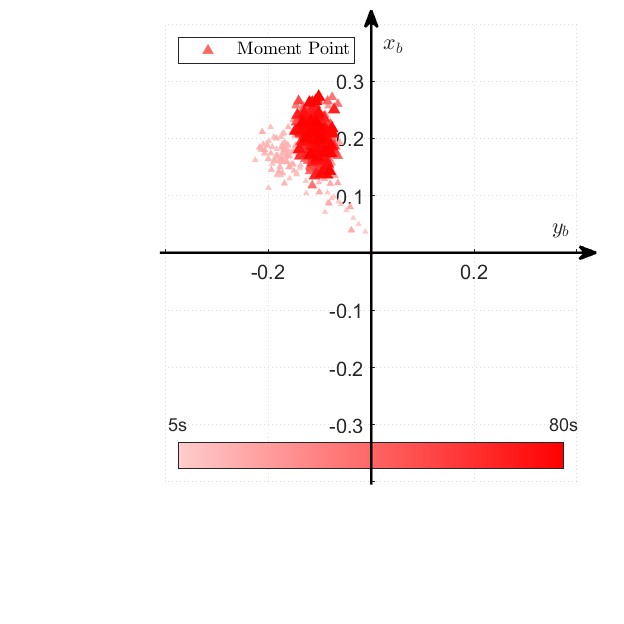

 
% 获取unknown_logger数据
logSampleRate = 10;
unknown_logger = msg.TopicMessages{34};
% 生成相对时间
log_time = unknown_logger.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);

% 获取数据
tDes = unknown_logger.tdes;
iter = unknown_logger.iter;

% 处理数据
% 选取和HIL中模型一致的控制分配矩阵参数
c  = (0.0166);
l  = (0.125);
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);
% 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
vAct = zeros(sample_count,4);
for i = 1:sample_count
    vAct(i,:) = M*((tDes(i,:))');
end
% 获取实际的包含故障信息的虚拟控制通道向量
vActFault = zeros(sample_count,4);
for i = 1:sample_count
    vActFault(i,:) = M*((tDes(i,:))'.*[0,1,1,1]');
end

%% 故障的时间段 20-80s
tfaultstart = 5;
tfaultend = 80;
samplevector = tfaultstart*logSampleRate:1:tfaultend*logSampleRate;
figure(12);
clf
[~,samplevectorLength] = size(samplevector);
% 第一条线的颜色大小
samplevectorcolorR = linspace(1, 1, samplevectorLength);
samplevectorcolorG = linspace(0.8, 0, samplevectorLength);
samplevectorcolorB = linspace(0.8, 0, samplevectorLength);
samplevectorcolor = [samplevectorcolorR; samplevectorcolorG; samplevectorcolorB];
% PosEcolor = 0:(1/(out.PosE.Length-1)):1;
colorMarker = samplevectorcolor;   % 颜色渐变
sizeMarker = linspace(10, 50, length(colorMarker));

scatter(vActFault(samplevector,3), vActFault(samplevector,2), sizeMarker, colorMarker','^', 'filled')
% scatter(vActFault(samplevector,3),vActFault(samplevector,2),'o','MarkerEdgeColor','#edb120');
xlim([-0.4 0.4])
ylim([-0.4 0.4])
xlabel("$y_b$",'Interpreter',"latex")
ylabel("$x_b$",'Interpreter',"latex")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
colormap(colorMarker');
colorbar( 'south','Ticks',[0,1],'TickLabels',{'5s','80s'})

annotation('arrow',[0.5949 0.5949],[0.2234 0.9835])
annotation('arrow',[0.2562 0.9553],[0.5950 0.5950])
legend("Moment Point", 'Interpreter',"latex",'Location',"northwest",'Box',"on")

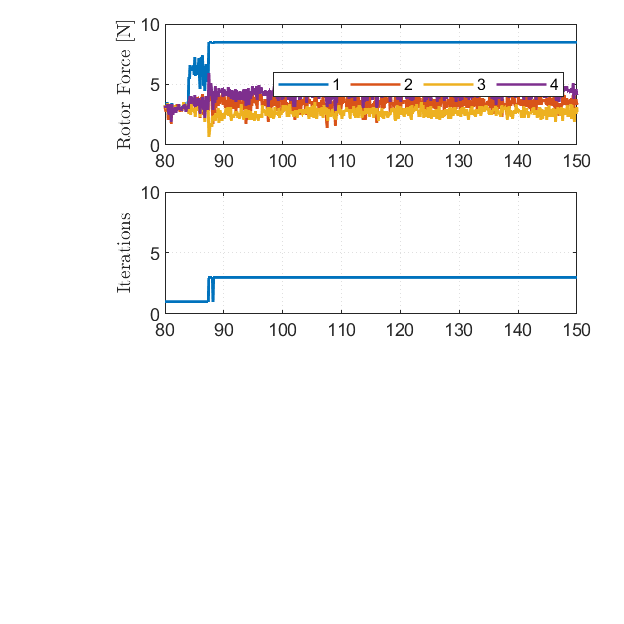

figure(11)
clf
subplot(3,1,1)
plot(time,tDes/5.5*8.5);
xlim([80,150])
ylabel('Rotor Force [N]','Interpreter',"latex")
legend('1','2','3','4','Orientation',"horizontal",'Location',"east")

subplot(3,1,2)
plot(time,iter)
xlim([80,150])
ylim([0,10])
ylabel('Iterations','Interpreter',"latex")

## 2.1旋转轴的估算

% 获取 vehicle_attitude 数据
logSampleRate = 250;
vehicle_attitude = msg.TopicMessages{38};
% 生成相对时间
log_time = vehicle_attitude.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 得到yaw为0的(无旋转的)旋转矩阵,并根据此得出机体旋转轴,相对的也可以理解为是地球坐标系的向量投射到机体系(无旋转)
% 左前方旋翼失效,俯仰角应该小于0, 横滚角应该大于0. 需要加上耦合项到控制器中
quate = vehicle_attitude.q;
quate(:,1) = quate(:,1);
[vehicle_attitude_psi, pitch, roll] = quat2angle(quate);%该矩阵可以将地球坐标系下的向量投射到机体坐标系,反之是将向量旋转-roll和-pitch
% 计算倾斜矩阵(无旋转)(e-->b)
yaw = zeros(sample_count,1);
angle = angle2dcm(yaw,pitch,roll);

% 利用倾斜矩阵计算旋转轴
rotation_axis = zeros(sample_count,3);
for i=1:sample_count
    % angle(:,:,i)*[0,0,1]' 看作是机体系的Z轴经过旋转矩阵旋转后的向量, 这是看作向量的旋转而非坐标系的转换.
    % 如何理解呢? 将手臂想象为旋转时候的旋转轴, 手握笔杆做一定的倾斜, 笔杆看作机体Z轴, 机体Z轴绕旋转轴旋转.
    % 当然确实可以看作是地球坐标系的Z轴在机体系中的投影(但是不便于解释), 因为旋转矩阵本身就有两种含义. 
    rotation_axis(i,:) = angle(:,:,i)*[0,0,1]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2.5,'SampleRate',20);
rotation_axis_xf = filtfilt(d,double(rotation_axis(:,1)));
rotation_axis_yf = filtfilt(d,double(rotation_axis(:,2)));
rotation_axis_zf = filtfilt(d,double(rotation_axis(:,3)));

% % 绘制欧拉角的图
% s = figure(21);
% clf
% subplot(2,1,1)
% plot(relativeTime,roll)
% % xlim([16, 19])
% 
% subplot(2,1,2)
% plot(relativeTime,pitch)
% xlim([16, 19])

%% 绘图主轴估计图
s = figure(22);
% s.Position(4) = 8.0;
clf
subplot(4,1,1)
% area(relativeTime,rotation_axis(:,1),'FaceColor','#c0e2c0','EdgeColor','#c0e2c0','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,'BaseValue',-0.02)
scatter(time,rotation_axis(:,1),'MarkerEdgeColor','#c0e2c0','MarkerFaceColor',"#c0e2c0",'MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(time,rotation_axis_xf,'LineWidth',1,'Color','#77AC30')
xlim([90,150])
% ylim([-0.1 0.03])
% xlabel("Time [s]",'Interpreter',"latex")
% ylabel("Rotation Axis $x_{\mathrm{b}}$","Interpreter","latex")
legend('$x$','Average of rotation axis $x$',"Interpreter","latex",'Location',"northeast",'Orientation',"horizontal")
legend('Box',"on",'FontSize',8)

subplot(4,1,2)
% area(relativeTime,rotation_axis(:,2),'FaceColor','#ffd8b7','EdgeColor','#ffd8b7','FaceAlpha',.3,'EdgeAlpha',.3,'ShowBaseLine',"off",'LineWidth',5,"BaseValue",0.1)
scatter(time,rotation_axis(:,2),'MarkerEdgeColor','#ffd8b7','MarkerFaceColor','#ffd8b7','MarkerEdgeAlpha',.3,'MarkerFaceAlpha',.3)
hold on
plot(time,rotation_axis_yf,'LineWidth',1,'Color','#ffa04d')
xlim([90,150])
% ylim([-0.3 0.2])
% xlabel("Time [s]",'Interpreter',"latex")
% ylabel("Rotation Axis $y_{\mathrm{b}}$","Interpreter","latex")
legend('$y$','Average of rotation axis $y$',"Interpreter","latex",'Location',"northeast",'Orientation',"horizontal")
legend('Box',"on",'FontSize',8)

## 2.2 旋转轴成形度

机体旋转轴在地球坐标系下的坐标

根据前面的部分可知, 机体的旋转轴在机体系下的`坐标大致为[0.02  0.15 0.9885]`

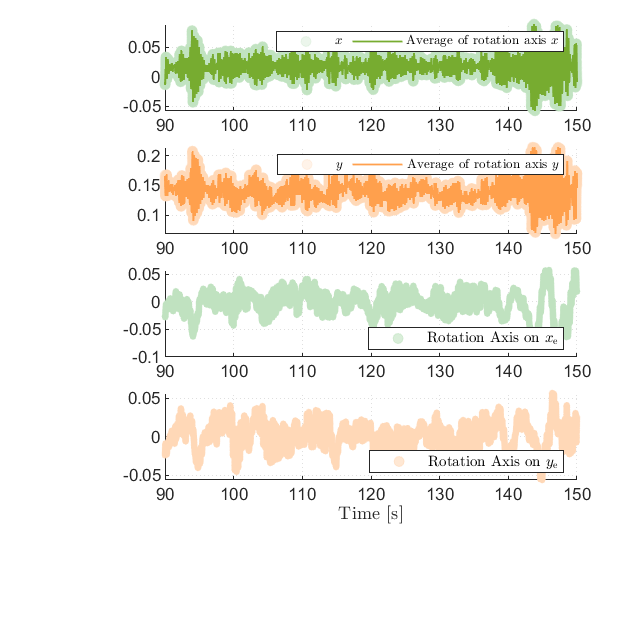

% 将四元数转换为旋转矩阵
vehicle_attitude_dcm = quat2dcm(quate);
% 利用旋转矩阵, 将估算出的机体旋转轴映射到地球坐标系中(旋转矩阵的顺序应该是将向量从及体系到地球系的转换即b-->e,而这里得出的矩阵是e-->b, 因此需要对矩阵进行转置)
rotation_axis_e = zeros(sample_count,3);
for i=1:sample_count
    rotation_axis_e(i,:) = vehicle_attitude_dcm(:,:,i)'*[0.02  0.15 0.9885]';
end
% 获取滤波数据 零相位滤波
d = designfilt('lowpassiir','FilterOrder',5,'HalfPowerFrequency',2,'SampleRate',20);
rotation_axis_e_xf = filtfilt(d,double(rotation_axis_e(:,1)));
rotation_axis_e_yf = filtfilt(d,double(rotation_axis_e(:,2)));
rotation_axis_e_zf = filtfilt(d,double(rotation_axis_e(:,3)));
% 绘制图像
figure(22)
% 滤波前的旋转轴在地球坐标系下的投影
% clf
subplot(4,1,3)
scatter(time,rotation_axis_e(:,1),12,'o','MarkerEdgeColor',"#c0e2c0","MarkerFaceColor","#c0e2c0","MarkerEdgeAlpha",0.6,"MarkerFaceAlpha",0.6)
% hold on
% plot(time,rotation_axis_e_xf,'Color','#77AC30','LineWidth',1.5)
xlim([90,150])
% xlabel("Time [s]",'Interpreter',"latex")
% ylabel("Rotation Axis on $x_\mathrm{e}$","Interpreter","latex")
legend("Rotation Axis on $x_\mathrm{e}$","Interpreter","latex",'Location',"best",'Orientation',"horizontal")

subplot(4,1,4)
scatter(time,rotation_axis_e(:,2),12,'o','MarkerEdgeColor',"#ffd8b7","MarkerFaceColor","#ffd8b7","MarkerEdgeAlpha",0.6,"MarkerFaceAlpha",0.6)
% hold on
% plot(time,rotation_axis_e_yf,'Color','#ffa04d','LineWidth',1.5)
xlim([90,150])
xlabel("Time [s]",'Interpreter',"latex")
% ylabel("Rotation Axis on $y_\mathrm{e}$","Interpreter","latex")
legend("Rotation Axis on $y_\mathrm{e}$","Interpreter","latex",'Location',"best",'Orientation',"horizontal")

## 3.机体角速率

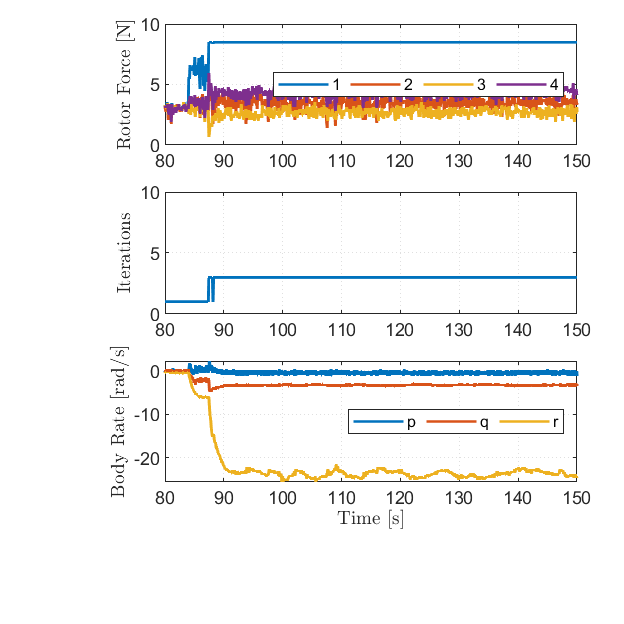

% 获取unknown_logger数据
logSampleRate = 160;
sensor_combined = msg.TopicMessages{23};
% 生成相对时间
log_time = sensor_combined.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
gyro = sensor_combined.gyro_rad;

% 画图
figure(11)
% clf
subplot(3,1,3)
plot(time, gyro)
xlabel('Time [s]', 'Interpreter',"latex")
ylabel('Body Rate [rad/s]', 'Interpreter',"latex")
legend('p','q','r','Orientation',"horizontal",'Location','east')
xlim([80,150])